# LAB5 MATLAB Programming

涂峻绫(12213010) and 欧阳安男(12211831)

## Introduction

MATLAB is a powerful tool to ......

## Results and Analysis

### 1

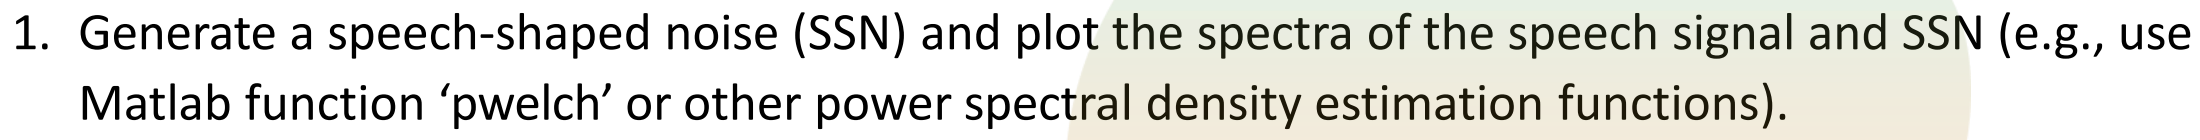

Load audio.

clear;clc;
[x, fs] = audioread('lab5/C_01_02.wav');
x = x';

Generate white noise.

whitenoise = 1-2*rand(1,length(x));

Generate long-term spectrum of speech signal to estimate the power spectral density of the speech signal.

sig = repmat(x,1,10);
[Pxx,f] =pwelch(sig, [], [], 512, fs);

Generate filter coefficients.

b = fir2(3000,f/(fs/2),sqrt(Pxx/max(Pxx)));

Perform filtering for white noise signal to get the SSN.

ssn = filter(b,1,whitenoise);

Get the spectra of the signal and SSN.

X = fftshift(fft(x)) / fs;
SSN = fftshift(fft(ssn)) / fs;
omega = linspace(-pi,pi,length(X)) * fs;

Plot the spectra of the signal and SSN.

figure;
subplot(2,1,1);
plot(omega,X);

title('the spectra of the signal');
xlabel('\omega');
ylabel('X(j\omega)');
subplot(2,1,2);
plot(omega,SSN);

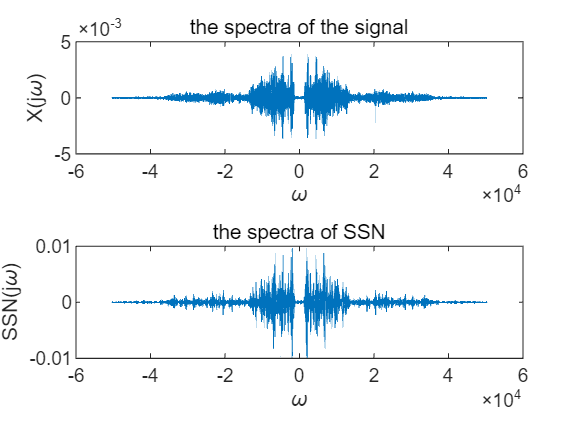

title('the spectra of SSN');
xlabel('\omega');
ylabel('SSN(j\omega)');

### 2

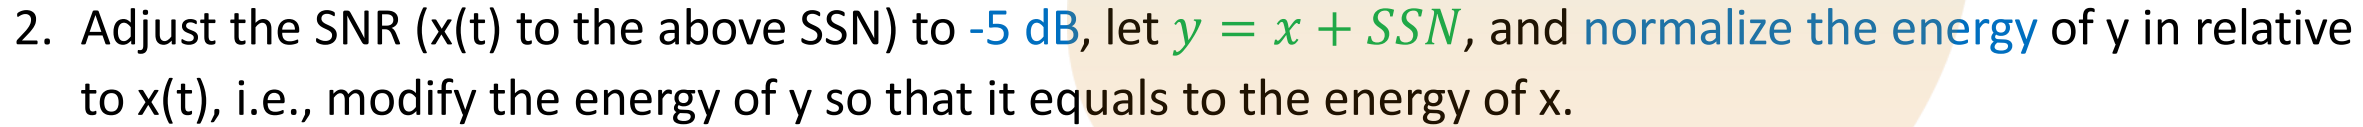

Adjust SNR.

X2 = X / sqrt(10);
x2 = ifft(ifftshift(X2)) * fs;

Generate y.

y = x2 + ssn;

Modify y.

y = (norm(x2)/norm(y)) * y;

Since floating point number comparison exist precision problem, when the difference between two floating point number is smaller than a very small value, we think they're the same.

abs(norm(y)-norm(x2)) < 1e-12

ans = logical
   1


Get the spectra of y.

Y = fftshift(fft(y)) / fs;

Plot the spectra of the adjusted SNR and y.

figure;
subplot(2,1,1);
plot(omega,X2);

title('the spectra of adjusted SNR');
xlabel('\omega');
ylabel('X_2(j\omega)');
subplot(2,1,2);
plot(omega,Y);

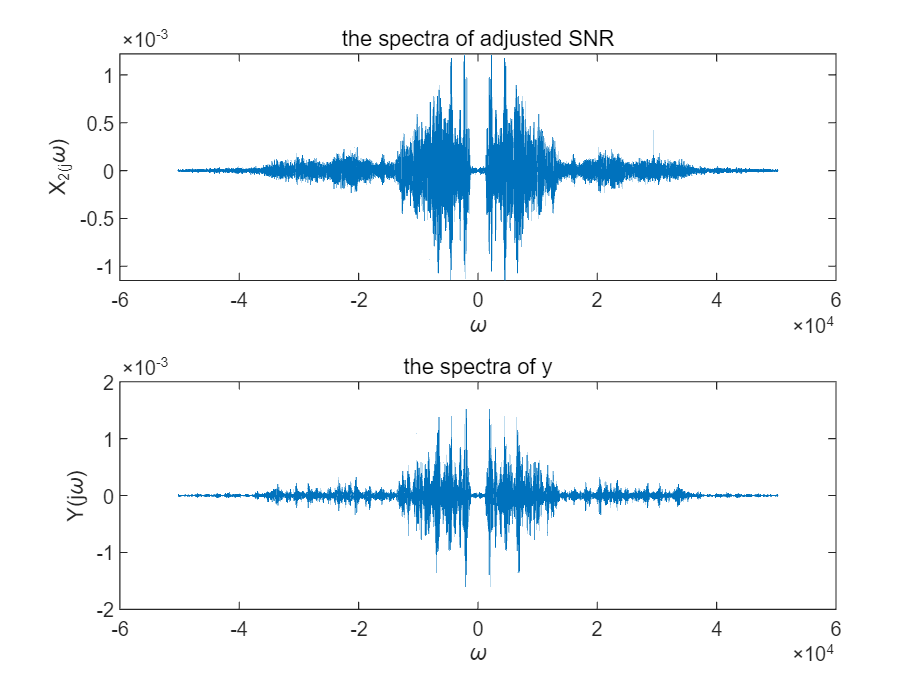

title('the spectra of y');
xlabel('\omega');
ylabel('Y(j\omega)');

### 3

#### 1)

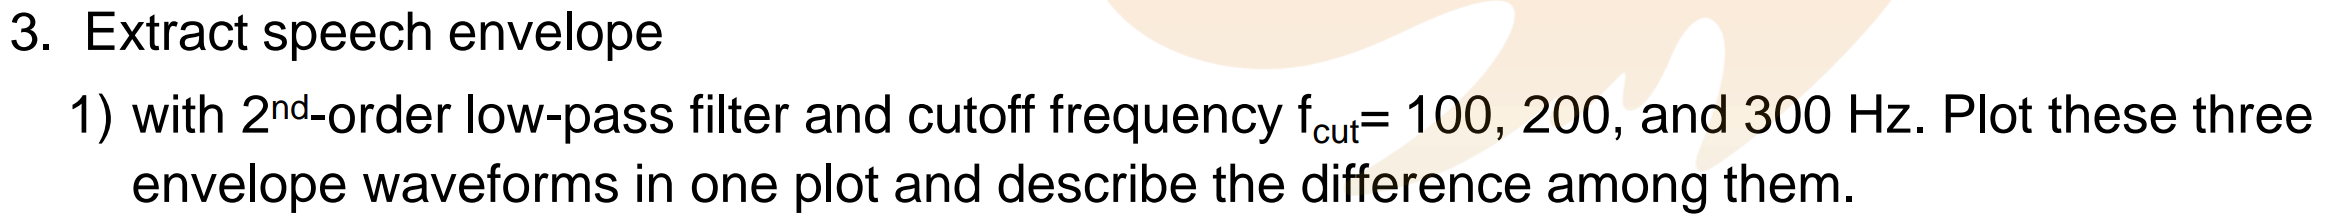

Get the filter coefficients of the three $2^{nd}$-order low-pass filters.

[b1,a1] = butter(2,100/(fs/2));
[b2,a2] = butter(2,200/(fs/2));
[b3,a3] = butter(2,300/(fs/2));

Get the three envelope waveforms of the signal.

y1 = filter(b1,a1,abs(x));
y2 = filter(b2,a2,abs(x));
y3 = filter(b3,a3,abs(x));

Plot them in one plot.

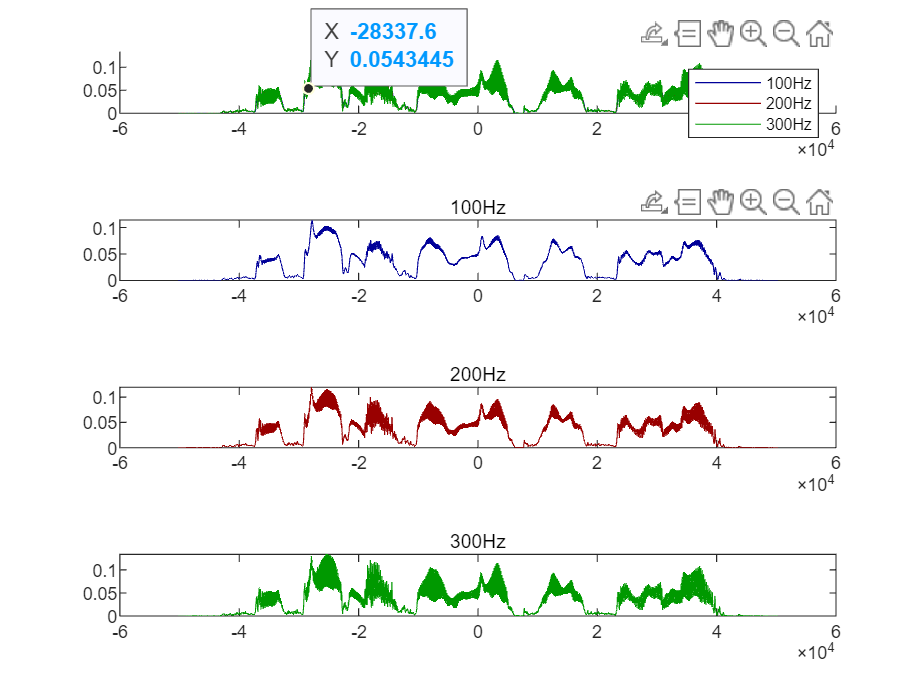

figure;
tiledlayout(4,1);
nexttile();
hold on;
plot(omega,y1,'Color',[0,0,0.6]);
plot(omega,y2,'Color',[0.6,0,0]);
plot(omega,y3,'Color',[0,0.6,0]);
legend('100Hz','200Hz','300Hz');
nexttile();
plot(omega,y1,'Color',[0,0,0.6]);
title('100Hz');
nexttile();
plot(omega,y2,'Color',[0.6,0,0]);
title('200Hz');
nexttile();
plot(omega,y3,'Color',[0,0.6,0]);
title('300Hz');

Since the dots of plot of 300Hz cutoff frequency are too dense, we re-plot the three different plots respectively.

From the comparsion of the plots, we can tell that with a lower cutoff frequency, the envelope waveforms can be more smooth.

With the increase of the cutoff frequency, the envelope waveform will be with more heavy fluctuation.

#### 2)

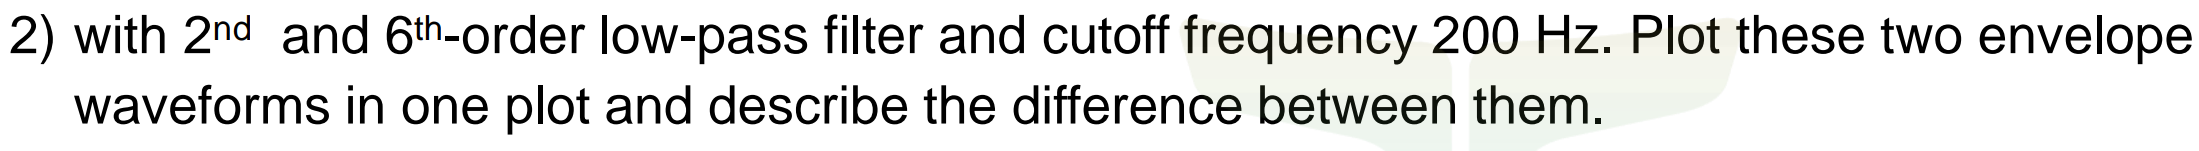

Get the filter coefficients of the $2^{nd}$-order and $6^{th}$-order low-pass filters.

[b4,a4] = butter(2,200/(fs/2));
[b5,a5] = butter(6,200/(fs/2));

Get the two envelope waveforms of the signal.

y4 = filter(b4,a4,abs(x));
y5 = filter(b5,a5,abs(x));

Plot them in one plot.

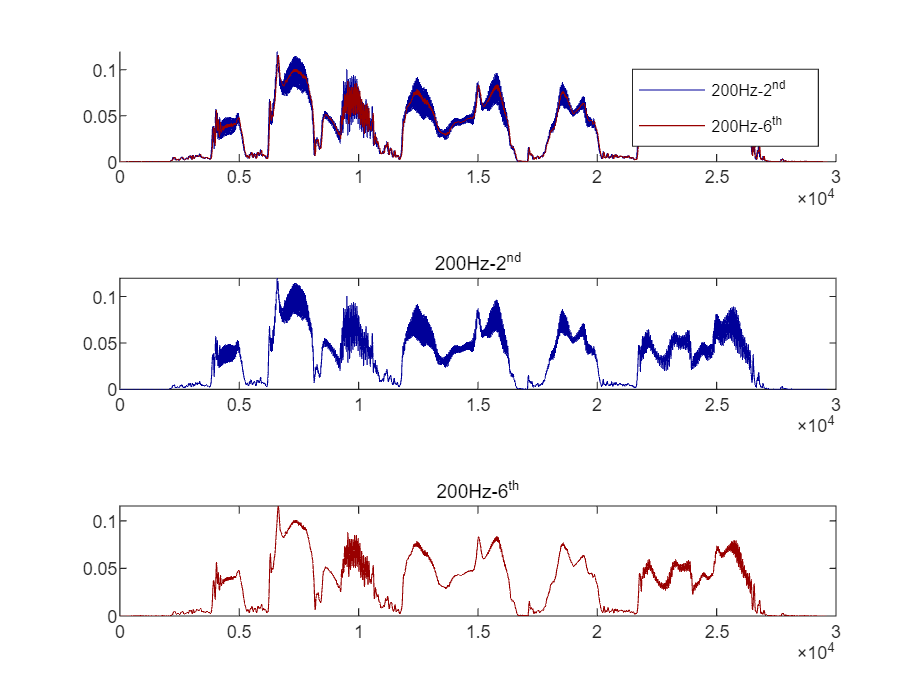

figure;
tiledlayout(6,4);
nexttile([2 4]);
hold on;
plot(abs(y4),'Color',[0,0,0.6]);
plot(abs(y5),'Color',[0.6,0,0]);
legend('200Hz-2^{nd}','200Hz-6^{th}');
nexttile([2 4]);
plot(abs(y4),'Color',[0,0,0.6]);
title('200Hz-2^{nd}');
nexttile([2 4]);
plot(abs(y5),'Color',[0.6,0,0]);
title('200Hz-6^{th}');

Since the dots of plot of $2^{nd}$-order are too dense, we re-plot the two different plots respectively.

From the plots, we can tell that, with a higher order, we can get a more smooth envelope waveform.

## Expeience

........................